# **RBE500: Foundations of Robotics **

# Week 5: Inverse Kinematics 

**Kathia Coronado**

*Robotics Engineering Graduate Student, Worcester Polytechnic Institute, Worcester, Massachussets, kcoronado@wpi.edu*

## Introduction

The goal of this assignment is to analyze a and Elbow manipulator, see figure 5.4, using both Forward kinematics (FK) and Inverse Kinematics (IK).

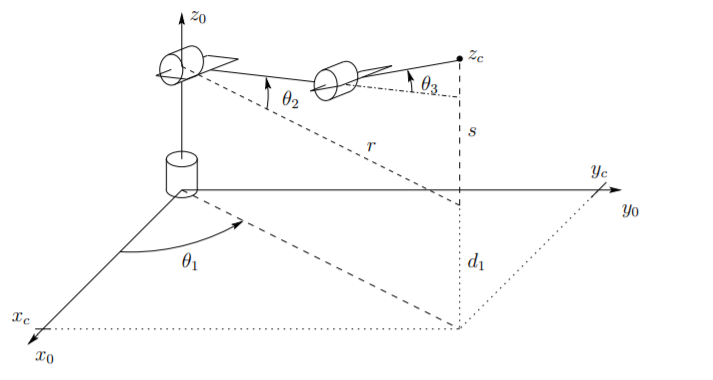

**Figure 5.4** - First three joints of an elbow manipulator

Inorder to achieve this goal the system was first studied using forward kinematics using the given DH parameter table, see table 5. Random joint values were assigned to the joint variables to solve for the corresponding position vectors.   Then the position vectors were used in the inverse kinematics calculation in order to recalculate the joint values. Inorder to aid in analysis, the two results were plotted and compared 

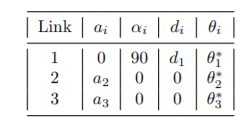 

Table 5.1 - DH parameters for the articulated manipulator of Figure 5.4

## Methods and Materials 

Answer: 

T = $\left(\begin{array}{cccc}
\mathrm{cos}\left(\theta_1 \right)\,\mathrm{cos}\left(\theta_2 \right)\,\mathrm{cos}\left(\theta_3 \right)-\mathrm{cos}\left(\theta_1 \right)\,\mathrm{sin}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right) & -\mathrm{cos}\left(\theta_1 \right)\,\mathrm{cos}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right)-\mathrm{cos}\left(\theta_1 \right)\,\mathrm{cos}\left(\theta_3 \right)\,\mathrm{sin}\left(\theta_2 \right) & \mathrm{sin}\left(\theta_1 \right) & l_2 \,\mathrm{cos}\left(\theta_1 \right)\,\mathrm{cos}\left(\theta_2 \right)+l_3 \,\mathrm{cos}\left(\theta_1 \right)\,\mathrm{cos}\left(\theta_2 \right)\,\mathrm{cos}\left(\theta_3 \right)-l_3 \,\mathrm{cos}\left(\theta_1 \right)\,\mathrm{sin}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right)\\
\mathrm{cos}\left(\theta_2 \right)\,\mathrm{cos}\left(\theta_3 \right)\,\mathrm{sin}\left(\theta_1 \right)-\mathrm{sin}\left(\theta_1 \right)\,\mathrm{sin}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right) & -\mathrm{cos}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_1 \right)\,\mathrm{sin}\left(\theta_3 \right)-\mathrm{cos}\left(\theta_3 \right)\,\mathrm{sin}\left(\theta_1 \right)\,\mathrm{sin}\left(\theta_2 \right) & -\mathrm{cos}\left(\theta_1 \right) & l_2 \,\mathrm{cos}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_1 \right)+l_3 \,\mathrm{cos}\left(\theta_2 \right)\,\mathrm{cos}\left(\theta_3 \right)\,\mathrm{sin}\left(\theta_1 \right)-l_3 \,\mathrm{sin}\left(\theta_1 \right)\,\mathrm{sin}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right)\\
\mathrm{cos}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right)+\mathrm{cos}\left(\theta_3 \right)\,\mathrm{sin}\left(\theta_2 \right) & \mathrm{cos}\left(\theta_2 \right)\,\mathrm{cos}\left(\theta_3 \right)-\mathrm{sin}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right) & 0 & l_1 +l_2 \,\mathrm{sin}\left(\theta_2 \right)+l_3 \,\mathrm{cos}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right)+l_3 \,\mathrm{cos}\left(\theta_3 \right)\,\mathrm{sin}\left(\theta_2 \right)\\
0 & 0 & 0 & 1
\end{array}\right)$ (4)

$\theta_2 =\textrm{Atan2}\left(s,x\right)-$$\textrm{acos}\left(\frac{\left(l_2^2 +r^2 \right)-l_3^2 \;}{2l_2 r}\right)$                                                                                                          (15)

$\theta_3$ = 180 $\left(180-\left(\textrm{acos}\left(\frac{\left(l_2^2 +r^2 \right)-l_3^2 \;}{2l_2 r}\right)+\textrm{acos}\left(\frac{\left(l_3^2 +r^2 \right)-l_2^2 \;}{2l_3 r}\right)\right)\right)$                                                             (16)

$\theta_1 =\textrm{Atan2}\left(y_c ,x_c \right)$                                                                                                                                             (17)

This weeks assigment involved using both forward and inverse kinematics to analyze an elbow manipulator. For the forward kinematics porttion of the assignment, the DH parameters given in table 5.1 were used to contruct  each of the sequential homogeneous transformation matrices.The DH method simplifies the analysis of a multi link manipulator by representing each HTM, $\,H_i$, as a product of four basic tranformations, see equation 3.10.

Using the DH parameters equation 3.10, in the textbook can be used to obtain the homogeneous tranformation matrix for each of the links in the system, see equations 1a-c.

$H_1^0 =\left\lbrack \begin{array}{cccc}
C\theta_1  & -S\theta_1 C\alpha_1  & S\theta_1 S\alpha_1  & a_1 C\theta_1 \\
S\theta_1  & C\theta_1 C\alpha_1  & -C\theta_1 S\alpha_1  & a_1 S\theta_1 \\
0 & S\alpha_1  & C\alpha_1  & d_1 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                            (1a)

$H_2^1 =\left\lbrack \begin{array}{cccc}
C\theta_2  & -S\theta_2 C\alpha_2  & S\theta_2 S\alpha_2  & a_2 C\theta_2 \\
S\theta_2  & C\theta_2 C\alpha_2  & -C\theta_2 S\alpha_2  & a_2 S\theta_2 \\
0 & S\alpha_2  & C\alpha_2  & d_2 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;$                                                                                            (1b)

$H_3^2 =\left\lbrack \begin{array}{cccc}
C\theta_3  & -S\theta_3 C\alpha_3  & S\theta_3 S\alpha_3  & a_3 C\theta_3 \\
S\theta_3  & C\theta_3 C\alpha_3  & -C\theta_3 S\alpha_3  & a_3 S\theta_3 \\
0 & S\alpha_3  & C\alpha_3  & d_3 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;$                                                                                            (1c)

Substituting the DH parameters in equations 1a-1c, with the appropriate and corresponding link parameters in table 1, the homogeneous transformation matrices for each link in the system can be determined, see equation 2a-2c.

$H_1^0 =$$\left(\begin{array}{cccc}
\mathrm{cos}\left(\frac{\pi \,\theta_1 }{180}\right) & 0 & \mathrm{sin}\left(\frac{\pi \,\theta_1 }{180}\right) & 0\\
\mathrm{sin}\left(\frac{\pi \,\theta_1 }{180}\right) & 0 & -\mathrm{cos}\left(\frac{\pi \,\theta_1 }{180}\right) & 0\\
0 & 1 & 0 & l_1 \\
0 & 0 & 0 & 1
\end{array}\right)$                                                                                                (2a)

$H_2^1 =$$\left(\begin{array}{cccc}
\mathrm{cos}\left(\frac{\pi \,\theta_2 }{180}\right) & -\mathrm{sin}\left(\frac{\pi \,\theta_2 }{180}\right) & 0 & l_2 \,\mathrm{cos}\left(\frac{\pi \,\theta_2 }{180}\right)\\
\mathrm{sin}\left(\frac{\pi \,\theta_2 }{180}\right) & \mathrm{cos}\left(\frac{\pi \,\theta_2 }{180}\right) & 0 & l_2 \,\mathrm{sin}\left(\frac{\pi \,\theta_2 }{180}\right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$                                                                              (2b)

$H_3^2 =$$\left(\begin{array}{cccc}
\mathrm{cos}\left(\frac{\pi \,\theta_3 }{180}\right) & -\mathrm{sin}\left(\frac{\pi \,\theta_3 }{180}\right) & 0 & l_3 \,\mathrm{cos}\left(\frac{\pi \,\theta_3 }{180}\right)\\
\mathrm{sin}\left(\frac{\pi \,\theta_3 }{180}\right) & \mathrm{cos}\left(\frac{\pi \,\theta_3 }{180}\right) & 0 & l_3 \,\mathrm{sin}\left(\frac{\pi \,\theta_3 }{180}\right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$                                                                             (2c)

Similar to the rules for the compositions of rotation matrices, see equation 2.22, since the second transformation,$H_2^1$, is performed relative to the current frame, then the previous rotation, $H_1^0$, is postmultiplied by the second transformation. third transformation,$H_3^2$, is performed relative to the current frame, then the previous rotation, $H_2^1$, is postmultiplied by the third transformation

the matrices in equation 2a -2c can be post multiplied sequentially to produce the homogeneos tranformation matrix from the base to end effector, $T$, see equation 3

 $T=H_1^0 H_2^1 H_3^2$                                                                                                                                           (3)

Substituting equations 2a-2c into equation 3, the transformation matrix of the system can be obtained, see equation 4. 

T = $\left(\begin{array}{cccc}
\mathrm{cos}\left(\theta_1 \right)\,\mathrm{cos}\left(\theta_2 \right)\,\mathrm{cos}\left(\theta_3 \right)-\mathrm{cos}\left(\theta_1 \right)\,\mathrm{sin}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right) & -\mathrm{cos}\left(\theta_1 \right)\,\mathrm{cos}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right)-\mathrm{cos}\left(\theta_1 \right)\,\mathrm{cos}\left(\theta_3 \right)\,\mathrm{sin}\left(\theta_2 \right) & \mathrm{sin}\left(\theta_1 \right) & l_2 \,\mathrm{cos}\left(\theta_1 \right)\,\mathrm{cos}\left(\theta_2 \right)+l_3 \,\mathrm{cos}\left(\theta_1 \right)\,\mathrm{cos}\left(\theta_2 \right)\,\mathrm{cos}\left(\theta_3 \right)-l_3 \,\mathrm{cos}\left(\theta_1 \right)\,\mathrm{sin}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right)\\
\mathrm{cos}\left(\theta_2 \right)\,\mathrm{cos}\left(\theta_3 \right)\,\mathrm{sin}\left(\theta_1 \right)-\mathrm{sin}\left(\theta_1 \right)\,\mathrm{sin}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right) & -\mathrm{cos}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_1 \right)\,\mathrm{sin}\left(\theta_3 \right)-\mathrm{cos}\left(\theta_3 \right)\,\mathrm{sin}\left(\theta_1 \right)\,\mathrm{sin}\left(\theta_2 \right) & -\mathrm{cos}\left(\theta_1 \right) & l_2 \,\mathrm{cos}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_1 \right)+l_3 \,\mathrm{cos}\left(\theta_2 \right)\,\mathrm{cos}\left(\theta_3 \right)\,\mathrm{sin}\left(\theta_1 \right)-l_3 \,\mathrm{sin}\left(\theta_1 \right)\,\mathrm{sin}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right)\\
\mathrm{cos}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right)+\mathrm{cos}\left(\theta_3 \right)\,\mathrm{sin}\left(\theta_2 \right) & \mathrm{cos}\left(\theta_2 \right)\,\mathrm{cos}\left(\theta_3 \right)-\mathrm{sin}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right) & 0 & l_1 +l_2 \,\mathrm{sin}\left(\theta_2 \right)+l_3 \,\mathrm{cos}\left(\theta_2 \right)\,\mathrm{sin}\left(\theta_3 \right)+l_3 \,\mathrm{cos}\left(\theta_3 \right)\,\mathrm{sin}\left(\theta_2 \right)\\
0 & 0 & 0 & 1
\end{array}\right)$ (4)

Once I calculated the tranformation matrix, I subsittuted random joint values, to obtain an array of position values, in which i would use for inverse kinematics. let $T_{\mathrm{sub}}$ be the transformation matrix with substitutions. To obtain the position vector of the system, I extracted the fourth column of the matrix, see equation 5.

$P_3^0 =$$T_{\mathrm{sub}}$**(:,4) **                                                                                                                                              (5)

For the inverse kinematic analysis, I used the position vector produced by the forward kinematics as input to calculated joint variables. Figure 1, displays a simplified top view diagram of the system. This diagram was useful for visualizing the system and calculating the forward kinematics.

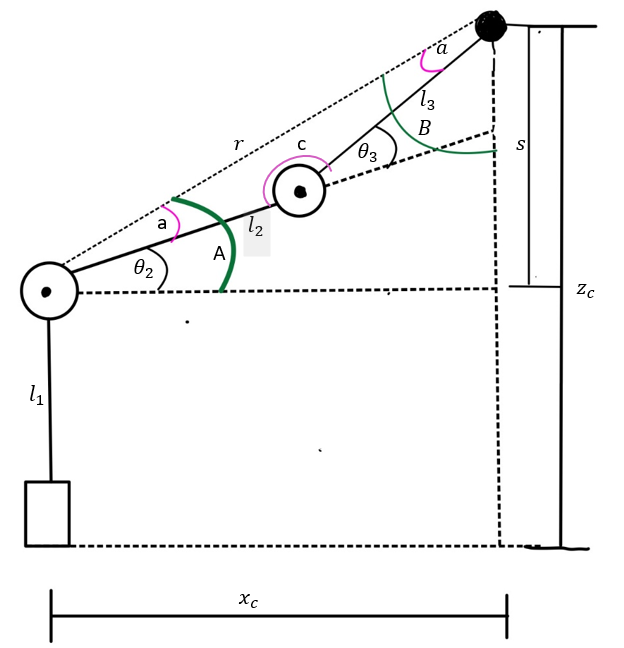

**Figure 1 - **Simple top view of the elbow manipulator 

I took a geometric inverse kinematic apprach at obtaining the joint values for the system. In order to get  the values I needed to Separate the figure 1 into two triangles: one large right triangle and one smaller triangle. Figure 2a and 2b highlight the triangles being analyzed. Figure 2a is the large triangle, figure 2b is the small triangle.

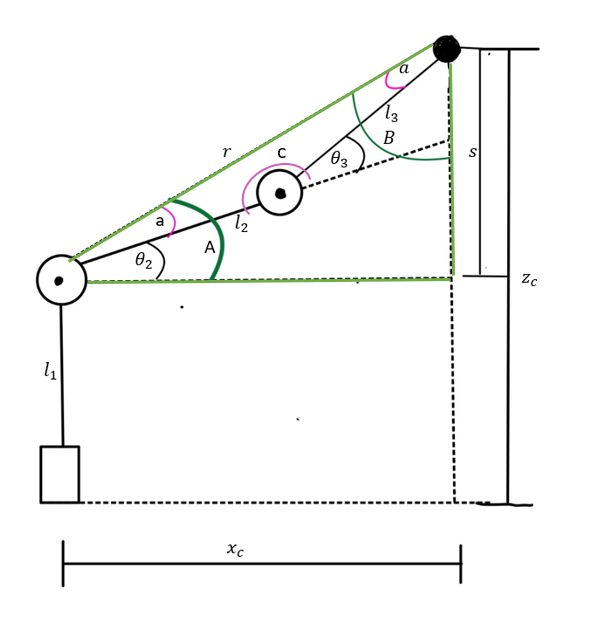

**Figure 2a** - Large triangle 

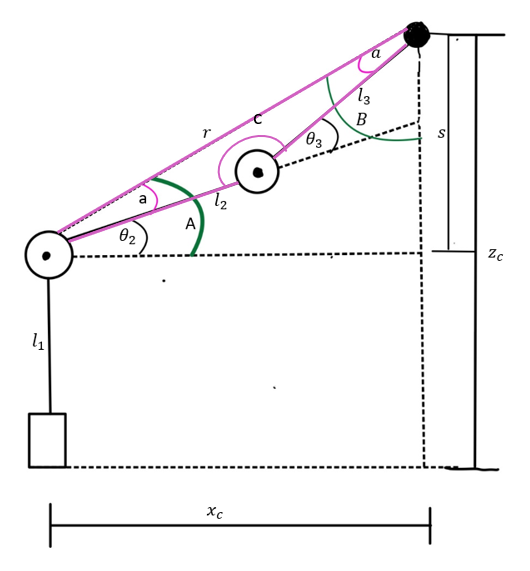

**Figure 2b** - small triangle

The small triangle is within the large one, due to this it is easy to solve for the joint variables. Angle $\theta_2$ is the difference between angle a and angle A, see equation 6. Angle c and angle $\theta_3$ form a straight line, therefore they add up to 180 degrees. Taking the difference between 180 degrees and angle c gives $\theta_2$, see equation 7.

$\theta_2$ = A -a                                                                                                                                                            (6)

$\theta_3$ = 180 -c                                                                                                                                                        (7)

To solve for the second and third joint variable, all the angles and lengths of the both triangles must be solved for. First, the big triangle will be analyzed. The length s, denoted by the figures, is distance in the z direction between the second joint and he end effector. This length can be solved by subtracting $l_1$ from the the position of the end effector in the z direction, see equation 8 . The length r can easily be solved using pythagorean theorem, since it is the hypothenuse of the big triangle, see equation 9.

$s=z_c -l_1 \;$                                                                                                                                                          (8)

$r=\sqrt{{x_c }^2 +s^2 }$                                                                                                                                                     (9)

With these two length, now all of the sides of the big triangle are know. Knowing the sides, the angles of the triangle, A and B,  can easily be found using Atan2, see equations 10 and 11. Atan2 is used instead of Atan because Atan2 takes into account the quandrant that the angle is in. 

A = Atan2 (s,$x_c$)                                                                                                                                                   (10)

B = Atan2 ($x_c$,s)                                                                                                                                                   (11)

Now all of the values of the big triangle are know.  To solve for the angle values of the small triangle, the law of cosines was used, see equations 12 and 13.

$a=\mathrm{acos}\left(\frac{\left(l_2^2 +r^2 \right)-l_3^2 \;}{2l_2 r}\right)$                                                                                                                                 (12)

$b=\mathrm{acos}\left(\frac{\left(l_3^2 +r^2 \right)-l_2^2 \;}{2l_3 r}\right)$                                                                                                                                 (13)

finally angle c need to be solved. Since two of the angles in the small triangle are known the third can easily be calculated, since the sum of all angles in a triangle are equal to 180 degress, see equation 14.

c = 180 - (a+b) = $180-\left(\mathrm{acos}\left(\frac{\left(l_2^2 +r^2 \right)-l_3^2 \;}{2l_2 r}\right)+\mathrm{acos}\left(\frac{\left(l_3^2 +r^2 \right)-l_2^2 \;}{2l_3 r}\right)\right)$                                                      (14)

Now that all of the variables except for the joint variables are know, values can be substituted into equations 6 and 7 to obtain the second and third joint value, see equation 15 and 16.

$\theta_2 =\mathrm{Atan2}\left(s,x_c \right)-$$\mathrm{acos}\left(\frac{\left(l_2^2 +r^2 \right)-l_3^2 \;}{2l_2 r}\right)$                                                                                                          (15)

$\theta_3$ = 180 $\left(180-\left(\mathrm{acos}\left(\frac{\left(l_2^2 +r^2 \right)-l_3^2 \;}{2l_2 r}\right)+\mathrm{acos}\left(\frac{\left(l_3^2 +r^2 \right)-l_2^2 \;}{2l_3 r}\right)\right)\right)$                                                              (16)

Solving for the first joint variable is very straight forwards. Looking at figure 5.4, it can be seen that the first joint variable can attained using simple trigonometry. We know the length of the vertices that make up the angle, there Atan2 can be used again to obtain the variable, see equation 17.

$\theta_1 =\mathrm{Atan2}\left(y_c ,x_c \right)$                                                                                                                                             (17)

## Results 

Inorder to analyze the elbow manipulator, forward and inverse kinematics were preformed on the system.

Declaration of  symbolic variables (link lengths and joint variables).

clear; clc ;
syms l_1 l_2 l_3 theta_1 theta_2 theta_3

#### Forward kinematics 

The given DH parameters for the system ( a, alpha, d and theta) are used to calculate the transformation matrix that relates the end effector to the base. 

a= [0 l_2 l_3];
alpha = [90 0 0];
d = [l_1 0 0];
theta = [theta_1 theta_2 theta_3];

Dh parameter function is called to get all of the sequential tranformation matrices.

A = GetDH (a, alpha,d,theta);
H01= A{1}

$$H01 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{1}}{180}\right) & 0 & \sin\left(\frac{\pi \,\theta_{1}}{180}\right) & 0\\ \sin\left(\frac{\pi \,\theta_{1}}{180}\right) & 0 & -\cos\left(\frac{\pi \,\theta_{1}}{180}\right) & 0\\ 0 & 1 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H12=A{2}

$$H12 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{2}}{180}\right) & -\sin\left(\frac{\pi \,\theta_{2}}{180}\right) & 0 & l_{2}\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right)\\ \sin\left(\frac{\pi \,\theta_{2}}{180}\right) & \cos\left(\frac{\pi \,\theta_{2}}{180}\right) & 0 & l_{2}\,\sin\left(\frac{\pi \,\theta_{2}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H23= A{3}

$$H23 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{3}}{180}\right) & -\sin\left(\frac{\pi \,\theta_{3}}{180}\right) & 0 & l_{3}\,\cos\left(\frac{\pi \,\theta_{3}}{180}\right)\\ \sin\left(\frac{\pi \,\theta_{3}}{180}\right) & \cos\left(\frac{\pi \,\theta_{3}}{180}\right) & 0 & l_{3}\,\sin\left(\frac{\pi \,\theta_{3}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T03 = simplify(A{1}*A{2}*A{3})

$$T03 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{5}\,\sigma_{3} & -\sigma_{1}\,\sigma_{3} & \sigma_{2} & \sigma_{3}\,\sigma_{4}\\ \sigma_{5}\,\sigma_{2} & -\sigma_{1}\,\sigma_{2} & -\sigma_{3} & \sigma_{2}\,\sigma_{4}\\ \sigma_{1} & \sigma_{5} & 0 & l_{1}+l_{3}\,\sigma_{1}+l_{2}\,\sin\left(\frac{\pi \,\theta_{2}}{180}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\left(\theta_{2}+\theta_{3}\right)}{180}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,\theta_{1}}{180}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,\theta_{1}}{180}\right)\\ \sigma_{4}=l_{3}\,\sigma_{5}+l_{2}\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right)\\ \sigma_{5}=\cos\left(\frac{\pi \,\left(\theta_{2}+\theta_{3}\right)}{180}\right) \end{array}$$

T02 = simplify(A{1}*A{2});
T01 = simplify(A{1});


Declaration of an array of 100 arbitrary joint values for each joint.

q1t = linspace(0,30,100);
q2t = linspace(0,80,100);
q3t = linspace(0,60,100);

extract the position vector from the Tranformation matrix 

pe = expand(T03(1:3,4));
pe_simp = simplify(pe);

x=pe_simp(1)

$$x = \cos\left(\frac{\pi \,\theta_{1}}{180}\right)\,\left(l_{3}\,\cos\left(\frac{\pi \,\left(\theta_{2}+\theta_{3}\right)}{180}\right)+l_{2}\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right)\right)$$

y=pe_simp(2)

$$y = \sin\left(\frac{\pi \,\theta_{1}}{180}\right)\,\left(l_{3}\,\cos\left(\frac{\pi \,\left(\theta_{2}+\theta_{3}\right)}{180}\right)+l_{2}\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right)\right)$$

z=pe_simp(3)

$$z = l_{1}+l_{3}\,\sin\left(\frac{\pi \,\left(\theta_{2}+\theta_{3}\right)}{180}\right)+l_{2}\,\sin\left(\frac{\pi \,\theta_{2}}{180}\right)$$

Substitute the joint values and link lengths into the position vectors

%position values for array
x_plot = subs(x,{theta_1 theta_2 theta_3 l_1 l_2 l_3},{q1t q2t q3t 1 1 1});
y_plot = subs(y,{theta_1 theta_2 theta_3 l_1 l_2 l_3},{q1t q2t q3t 1 1 1});
z_plot = subs(z,{theta_1 theta_2 theta_3 l_1 l_2 l_3},{q1t q2t q3t 1 1 1});

Plot the position of the end effect 

display( 'PLOT 1: plot of the system end effector ')

PLOT 1: plot of the system end effector 


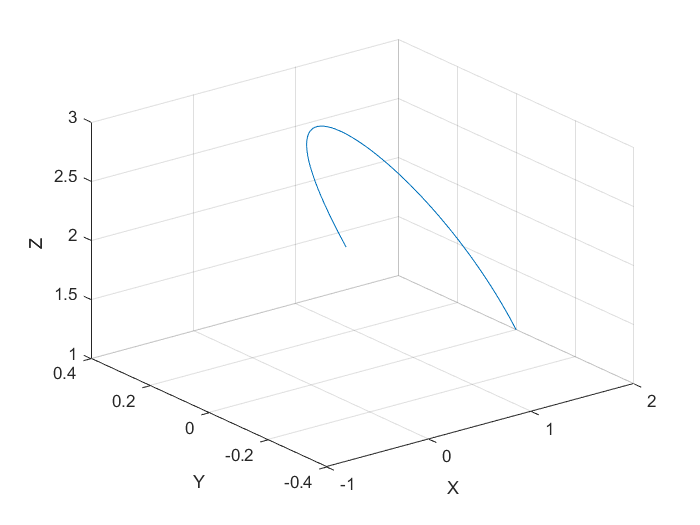

plot3(x_plot,y_plot,z_plot)
grid on
xlabel('X ')
ylabel('Y ')
zlabel('Z ')

#### Inverse kinematics 

Loop through all of the points. Use the position vectors, calculated via forward kinematics, as the input for inverse kinematics.


for i = 1: length(x_plot)
xe = double(x_plot(i));
ye = double(y_plot(i));
ze = double(z_plot(i));


Geometric equations for the lengths of the that aided in calculating the the joint variables 

s = double(subs(ze - l_1,{ l_1},{ 1}));
r = double(sqrt(s^2+xe^2));

Geometric equations for all of the angles that aided in calculating the joint variables 

A and B are the angles associated with the bigger of the two triangles analyzed for this problem 

a and b are the angles of the smaller triangle 

A = double(atan2d(s,xe));
B = double(atan2d(xe,s));
a = acosd(((l_2^2 +r^2) - l_3^2)/(2*l_2*r));
b = acosd(((l_3^2 +r^2) - l_2^2)/(2*l_3*r));
c = 180 - (a+b);

Substitute all of the values calculated above and solve for the joint variables for each position


th1 = double(subs(atan2d(ye, xe), {l_1 l_2 l_3},{ 1 1 1}));
th2 = double(subs(A -a, {l_1 l_2 l_3},{ 1 1 1}));
th3 = double(subs(180 -c, {l_1 l_2 l_3},{ 1 1 1}));

Append the position to an array, to store all of the values 

theta1(i)=th1;
theta2(i)=th2;
theta3(i)=th3;
end


Plot all of the joint variables values 

display ('PLOT 2: Plot of System joint variables')

PLOT 2: Plot of System joint variables


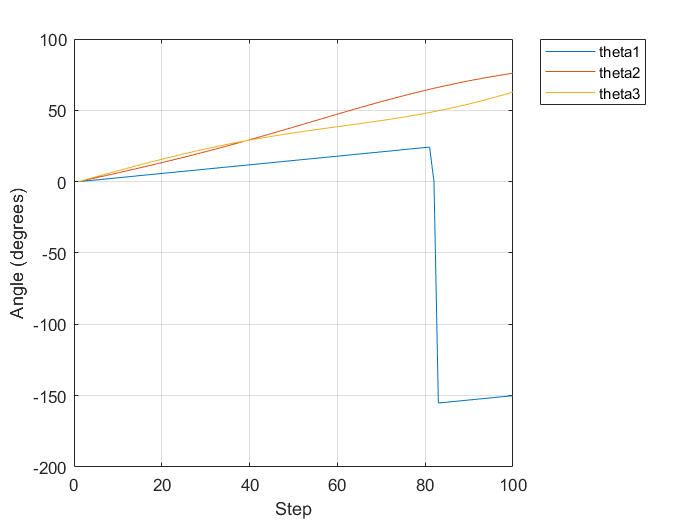

plot(theta1)
hold on
plot(theta2)
hold on 
plot(theta3)
grid on
legend('theta1','theta2','theta3')
ylabel('Angle (degrees)')
xlabel('Step')

### Functions 

This function uses the DH parameter to calculated the HTM using the DH method. This function will work for any number of joints. The output of this function is a cell array.

function A = GetDH (a, alpha,d,theta)
A = {};
for i = (1:length(a))
    
    H = [ cosd(theta(i)) -sind(theta(i))*cosd(alpha(i)) sind(theta(i))*sind(alpha(i)) a(i)*cosd(theta(i));
         sind(theta(i)) cosd(theta(i))*cosd(alpha(i)) -cosd(theta(i))*sind(alpha(i)) a(i)*sind(theta(i));
         0 sind(alpha(i)) cosd(alpha(i)) d(i);
         0 0 0 1];
    A{i}= H;
end
end


## Discussion

This assignment involved using inverse and forward kinematics on an elbow manipulator robot. The assignment was very interesting as it allowed me to better visualize and understand the outcome of IK and FK analyses. It also allowed be to better visuazlie and comprehend  how devastating singularities can be. In this assingment, I chose random joint values for the three joints of the system did FK, to find the Transformation matrix that related the end effector to the base, and then plotted the position vector of the system, see plot 1. Plot 1 looks to be correct for the parameters I chose. The chosen joint variables are all increasing at the same time, it makes sense that the resulting graph is a loop. 

 I then used the resulting position vector of the FK and inputted that into IK and solved for the joint values associated with that position. I then plotted the joint values, see plot 2. Plot 2 is  very interesting and is my favorite plot in this assignment. The second and third joint variables start at 0 and then gradually and steadily increase, this behavior is expected as the joint values that produced the the inputted position vector were increasing steadily by a counters.  the first joint however, behaved diffferently. It increased steadily up until the 80 step, then it dips down sharply and then continues to rise again. The dip is indicative of a singularity. The fact that the system experiences a singularity is a very important in the real world, as the opperator and or prgrammer will try to avoid a singular configuration as it could be detrimental to the task that the robot needs to accomplish. All in all this assignment was very interesting and insightful, as it allowed be to gain more experience with IK and FK as well as gave me a better understanding of singularities.

## Reference 

(1) Spong et al. (2020).* Robot Modeling and Control *(2nd Edition). Wiley.